%develope the code pipeline to process lfp data
global MONKEYDIR
MONKEYDIR = 'C:/Users/Orsborn Lab/OneDrive - UW/projects/Brain EEG/data';
addpath(genpath([MONKEYDIR '/m/']))
drive_base = 'LM1_ECOG';
    
%get sessions for 'drive' of interest
driveSessions = makeDriveDatabase(drive_base,{'180328','180328'});
Sessions = cat(1, driveSessions{:});
driveNames = Sessions(:,3);
driveNameAnalyze = {'LM1_ECOG_3'};
useSess          = ismember(driveNames, driveNameAnalyze);
DayAnalyze = Sessions(useSess,1);


%develope the code for single day
%trial load info
trialInfo.sequence_random = 1; 
trialInfo.filterAcq = 1;
trialInfo.filterAcq_time = 5;

trialInfo.tBefore = -1.2e3;
trialInfo.tAfter  = 1e3;
trialInfo.timeReachStart = abs(trialInfo.tBefore);
trialInfo.trig = 'ReachStart';
trialInfo.lfpType = 'lfp';
trialInfo.Fs_lfp = 1000;

trialInfo.proc_electrodes = [1 217];

%parameters to
feaParams.freqBands = [0 12;12 38;38 80;80 200];
feaParams.timeROIs = [-0.2 0;0 0.2] %in seconds

feaParams = struct with fields:
    freqBands: [4×2 double]
     timeROIs: [2×2 double]



%use constant target
selectedfile = 'C:\Users\Orsborn Lab\OneDrive - UW\projects\Brain EEG\code\posTargets_180328.mat';
load(selectedfile)

%we load the regular trials
SessAnalyze = Sessions(useSess,:);
nSess = size(SessAnalyze,1);

%load the frequency spectrum
freqParams.tapers = [0.2 5];
freqParams.Fs = 1000;
freqParams.dn = 0.02;        
freqParams.contFlag = 1;
freqParams.freqRange = [0 200]

freqParams = struct with fields:
       tapers: [0.2000 5]
           Fs: 1000
     contFlag: 1
    freqRange: [0 200]




class_results = nan(nSess,length(trialInfo.proc_electrodes));

Sessions_empty = [];
%remove any empty sessions
for iD=1:nSess
    
    trFN = [MONKEYDIR '/' DayAnalyze{iD} '/mat/Trials.mat'];
    load(trFN,'Trials')
    
    %filter out trials
    if trialInfo.sequence_random
        v = [Trials.SequenceRandom];
        Trials = Trials(v ==1);        
    end
    if isempty(unique({Trials.Rec}))
        Sessions_empty = [Sessions_empty iD];    
        disp(['Empty trials for day: ' DayAnalyze{iD}])
    end
    
    day_recs{iD,1} = unique({Trials.Rec});
    day_recs{iD,2} = {DayAnalyze{iD}};
    
end

Sessions(Sessions_empty,:) = [];

%the main processing loop

trLfpData_spec = [];

for iD=1:nSess
    
    trFN = [MONKEYDIR '/' DayAnalyze{iD} '/mat/Trials.mat'];
    load(trFN,'Trials')
    
    trialInfo.sessName =  DayAnalyze{iD};
    trialInfo.depthProfile = (Trials(1).Depth{1,2})'; % in micron
    
    %filter out trials
    if trialInfo.sequence_random
        v = [Trials.SequenceRandom];
        Trials = Trials(v ==1);        
    end
    if trialInfo.filterAcq
        stopToAcq = [Trials.ReachStop] - [Trials.TargAq];
        v = abs(stopToAcq) <= trialInfo.filterAcq_time;
        Trials = Trials(v);
    end
    trialInfo.num_trials = length(Trials);
   
    
    %load the trials
    %first load an experiment trial
    expFN = [MONKEYDIR '/' DayAnalyze{iD} '/' Trials(1).Rec '/rec' Trials(1).Rec '.experiment.mat'];
    load(expFN,'experiment')
    
    driveNameAnalyze = 'LM1_ECOG_3';
    drive_idx = 1; %1 for ECOG and 2 for SC3
    dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
    data_ECOG = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);
    
    %implement common averaging filter
    data_ECOG_mean = mean(data_ECOG,2);
    data_ECOG = data_ECOG - repmat(data_ECOG_mean,1,size(data_ECOG,2),1);
    
    driveNameAnalyze = 'LM1_SC32_1';
    drive_idx = 2; %1 for ECOG and 2 for SC32
    dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
    data_SC32 = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);
    
    trLfpData = cat(2,data_ECOG, data_SC32);
    
    clear data_SC32
    clear data_ECOG
   
    %do target sorting
    [Pos, targids] = calcSeqReachTarg(Trials);
    Pos_Seq_1 = squeeze(Pos(:,2,:));
    trial_TargetAssigned = assignTaskNumber(Pos_Seq_1_unique,Pos_Seq_1);
    
    %do time frequency analysis on each of the electrode
    for ti = 1:trialInfo.num_trials
        
        %figure out normalization period
        timeAqGo = Trials(ti).StartAq - Trials(ti).ReachStart + trialInfo.timeReachStart;
        timeTargsOn = Trials(ti).TargsOn - Trials(ti).ReachStart + trialInfo.timeReachStart;
        
        if timeAqGo <=0 || timeTargsOn <=0 
            disp([DayAnalyze{iD} ': Trial ' num2str(ti)])
            continue            
        end
        
        for e_index = 1:length(trialInfo.proc_electrodes) %look at only 1 electrode for now
            ei = trialInfo.proc_electrodes(e_index);
            dataTemp = squeeze(trLfpData(ti,ei,:));
            dataTemp = dataTemp / norm(dataTemp);
            
            dataTemp = dataTemp(timeAqGo:timeTargsOn);
            %do frequency calculation
            dat = dataTemp';
            [s, freq] = tfspec(dat, freqParams.tapers, freqParams.Fs, freqParams.dn, [], [], [], [], freqParams.contFlag);
            
            s_n_mean = squeeze(mean(s));
            s_n_std = squeeze(std(s));
            
            %reload the data
            dataTemp = squeeze(trLfpData(ti,ei,:));
            dataTemp = dataTemp / norm(dataTemp);
            dat = dataTemp';
            [s, freq] = tfspec(dat, freqParams.tapers, freqParams.Fs, freqParam.dn, [], [], [], [], freqParams.contFlag);
            
            %get z-score
            sN = size(s,1);
            s_z = (s - repmat(s_n_mean,sN,1)) ./ repmat(s_n_std,sN,1);
            
            trLfpData_spec(ti,e_index,:,:) = s_z;
               
        end
    end
    disp(['Finished: ' DayAnalyze{iD} ' spectrum calc'])
   
    
    saveFn = [MONKEYDIR '/' DayAnalyze{iD} '/mat/results_spectrum_0127.mat'];
    save(saveFn,"trialInfo","trial_TargetAssigned", "trLfpData_spec");
    trialInfo_all(iD) = trialInfo;
    
    disp(['Finished: ' DayAnalyze{iD} ' Classification'])
    disp('done')
    
end

Finished: 180328 spectrum calc


Finished: 180328 Classification


done


%save('results_all_allelectrodes',"trialInfo_all","class_results")

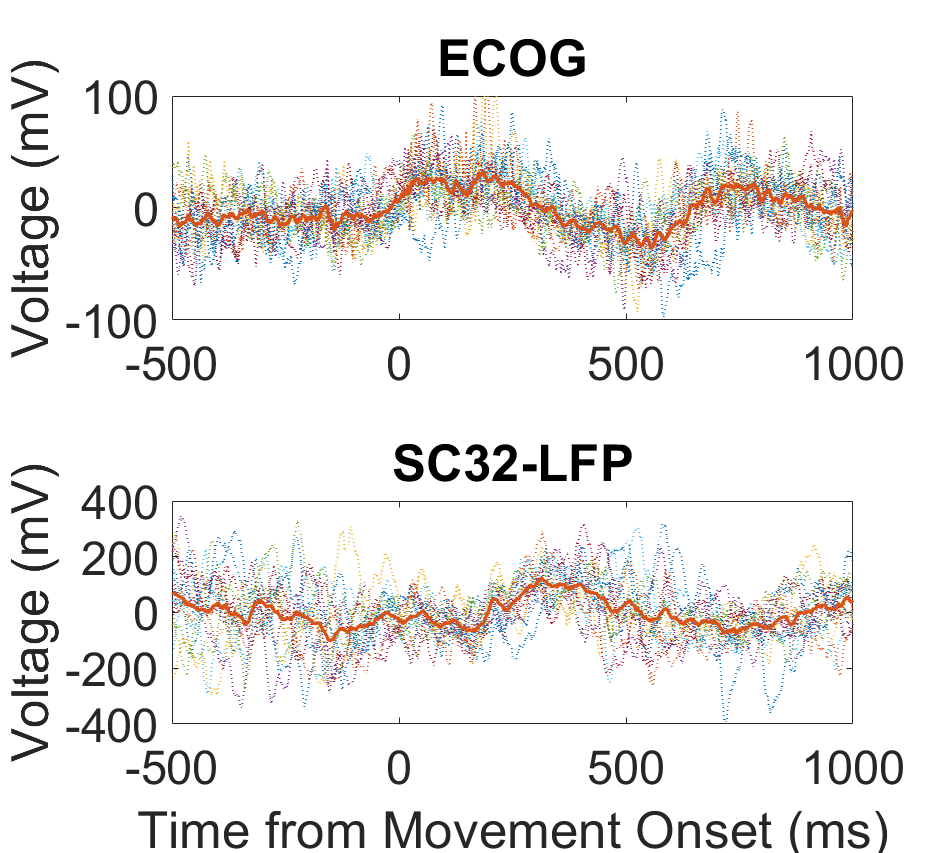

figure('units','normalized','outerposition',[0 0 0.5 0.75])
targ_i = 1;
ei = 1;

time_vec = (trialInfo.tBefore+1):trialInfo.tAfter;

subplot(2,1,1)
data_temp = squeeze((trLfpData(trial_TargetAssigned==targ_i,ei,:)));
plot(time_vec,data_temp,':','LineWidth', 1)
hold on
plot(time_vec,mean(data_temp),'LineWidth', 2)
hold off
ylabel('Voltage (mV)')
title('ECOG')
axis([-500 1000 -100 100])
set(gca, 'fontSize',28)

subplot(2,1,2)
ei = 217;
data_temp = squeeze((trLfpData(trial_TargetAssigned==targ_i,ei,:)));
plot(time_vec,data_temp,':','LineWidth', 1)
hold on
plot(time_vec,mean(data_temp),'LineWidth', 2)
hold off
ylabel('Voltage (mV)')
xlabel('Time from Movement Onset (ms)')
title('SC32-LFP')
axis([-500 1000 -400 400])
set(gca, 'fontSize',28)
print(gcf, 'centerout_ti.jpg', '-djpeg', '-r600');

Different motor potential features on this plot



exFeatureParams.timeROI = [-0.4 0.4];
exFeatureParams.freqROI = [0 100];
tick_spacing = 10;


s_length = size(trLfpData_spec,3)

s_length = 100

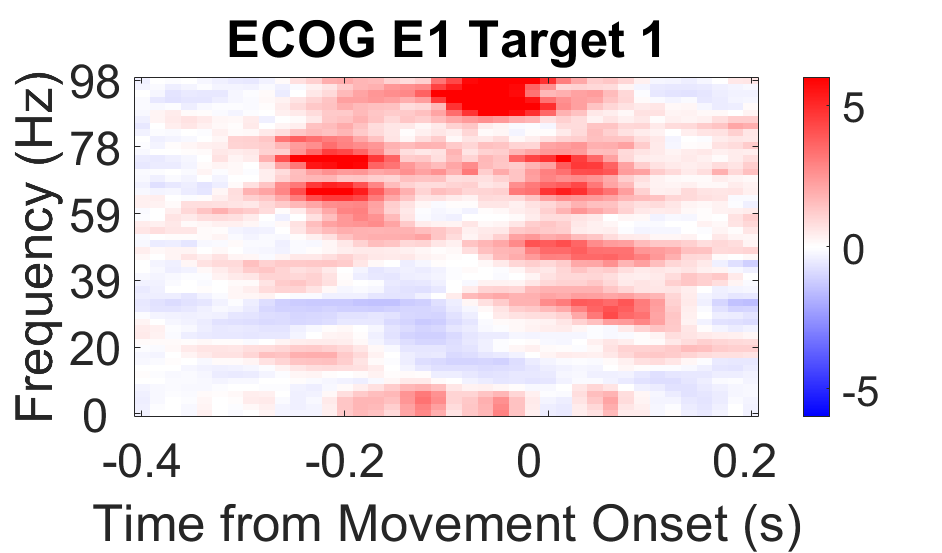

s_timePoints = freqParams.tapers(1)* 0.5 +(1:s_length)*freqParams.dn + trialInfo_all(1).tBefore / 1000;

time_indices = find((s_timePoints <= exFeatureParams.timeROI(2)) ...
                & (s_timePoints >= exFeatureParams.timeROI(1))) ;
freq_indices = find(freq <= exFeatureParams.freqROI(2) ...
                & freq >= exFeatureParams.freqROI(1)) ; 


figure('units','normalized','outerposition',[0 0 0.5 0.5])
targ_i = 1;
ei = 1;
data_temp = squeeze(mean(trLfpData_spec(trial_TargetAssigned == targ_i,ei,time_indices,freq_indices)));
imagesc(data_temp')
axis xy
colormap(redblue)
colorbar
caxis([-6 6])

yticklabels = freq(freq_indices);
yticklabels = round(yticklabels(1:tick_spacing:end));
yticks = linspace(1, size(data_temp, 2), ...
            numel(yticklabels));
set(gca, 'yTick', yticks, 'yTickLabel', yticklabels)
ylabel('Frequency (Hz)')

xticklabels = round(s_timePoints(time_indices),2);
xticklabels = xticklabels(1:tick_spacing:end);
xticks = linspace(1, size(data_temp, 1), ...
                numel(xticklabels));
set(gca, 'xTick', xticks, 'xTickLabel', xticklabels)
xlabel('Time from Movement Onset (s)')
title('ECOG E1 Target 1')


set(gca,'fontSize',28)
print(gcf, 'centerout_spectrum_ECOG.jpg', '-djpeg', '-r600');

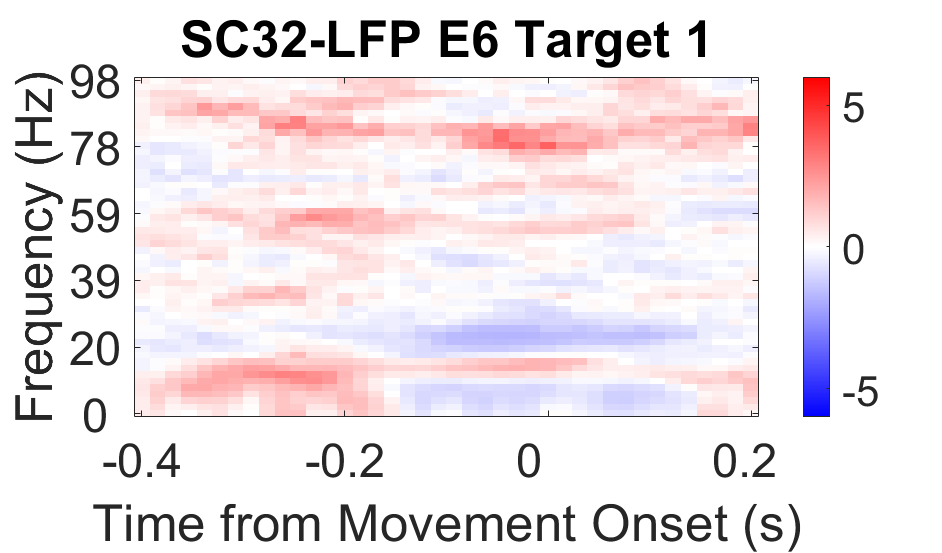


figure('units','normalized','outerposition',[0 0 0.5 0.5])
ei = 2;
data_temp = squeeze(mean(trLfpData_spec(trial_TargetAssigned == targ_i,ei,time_indices,freq_indices)));
imagesc(data_temp')
axis xy
colormap(redblue)
colorbar
caxis([-6 6])

yticklabels = freq(freq_indices);
yticklabels = round(yticklabels(1:tick_spacing:end));
yticks = linspace(1, size(data_temp, 2), ...
            numel(yticklabels));
set(gca, 'yTick', yticks, 'yTickLabel', yticklabels)
ylabel('Frequency (Hz)')

xticklabels = round(s_timePoints(time_indices),2);
xticklabels = xticklabels(1:tick_spacing:end);
xticks = linspace(1, size(data_temp, 1), ...
                numel(xticklabels));
set(gca, 'xTick', xticks, 'xTickLabel', xticklabels)
xlabel('Time from Movement Onset (s)')
title('SC32-LFP E6 Target 1')

set(gca,'fontSize',28) 

print(gcf, 'centerout_spectrum_SC32.jpg', '-djpeg', '-r600');

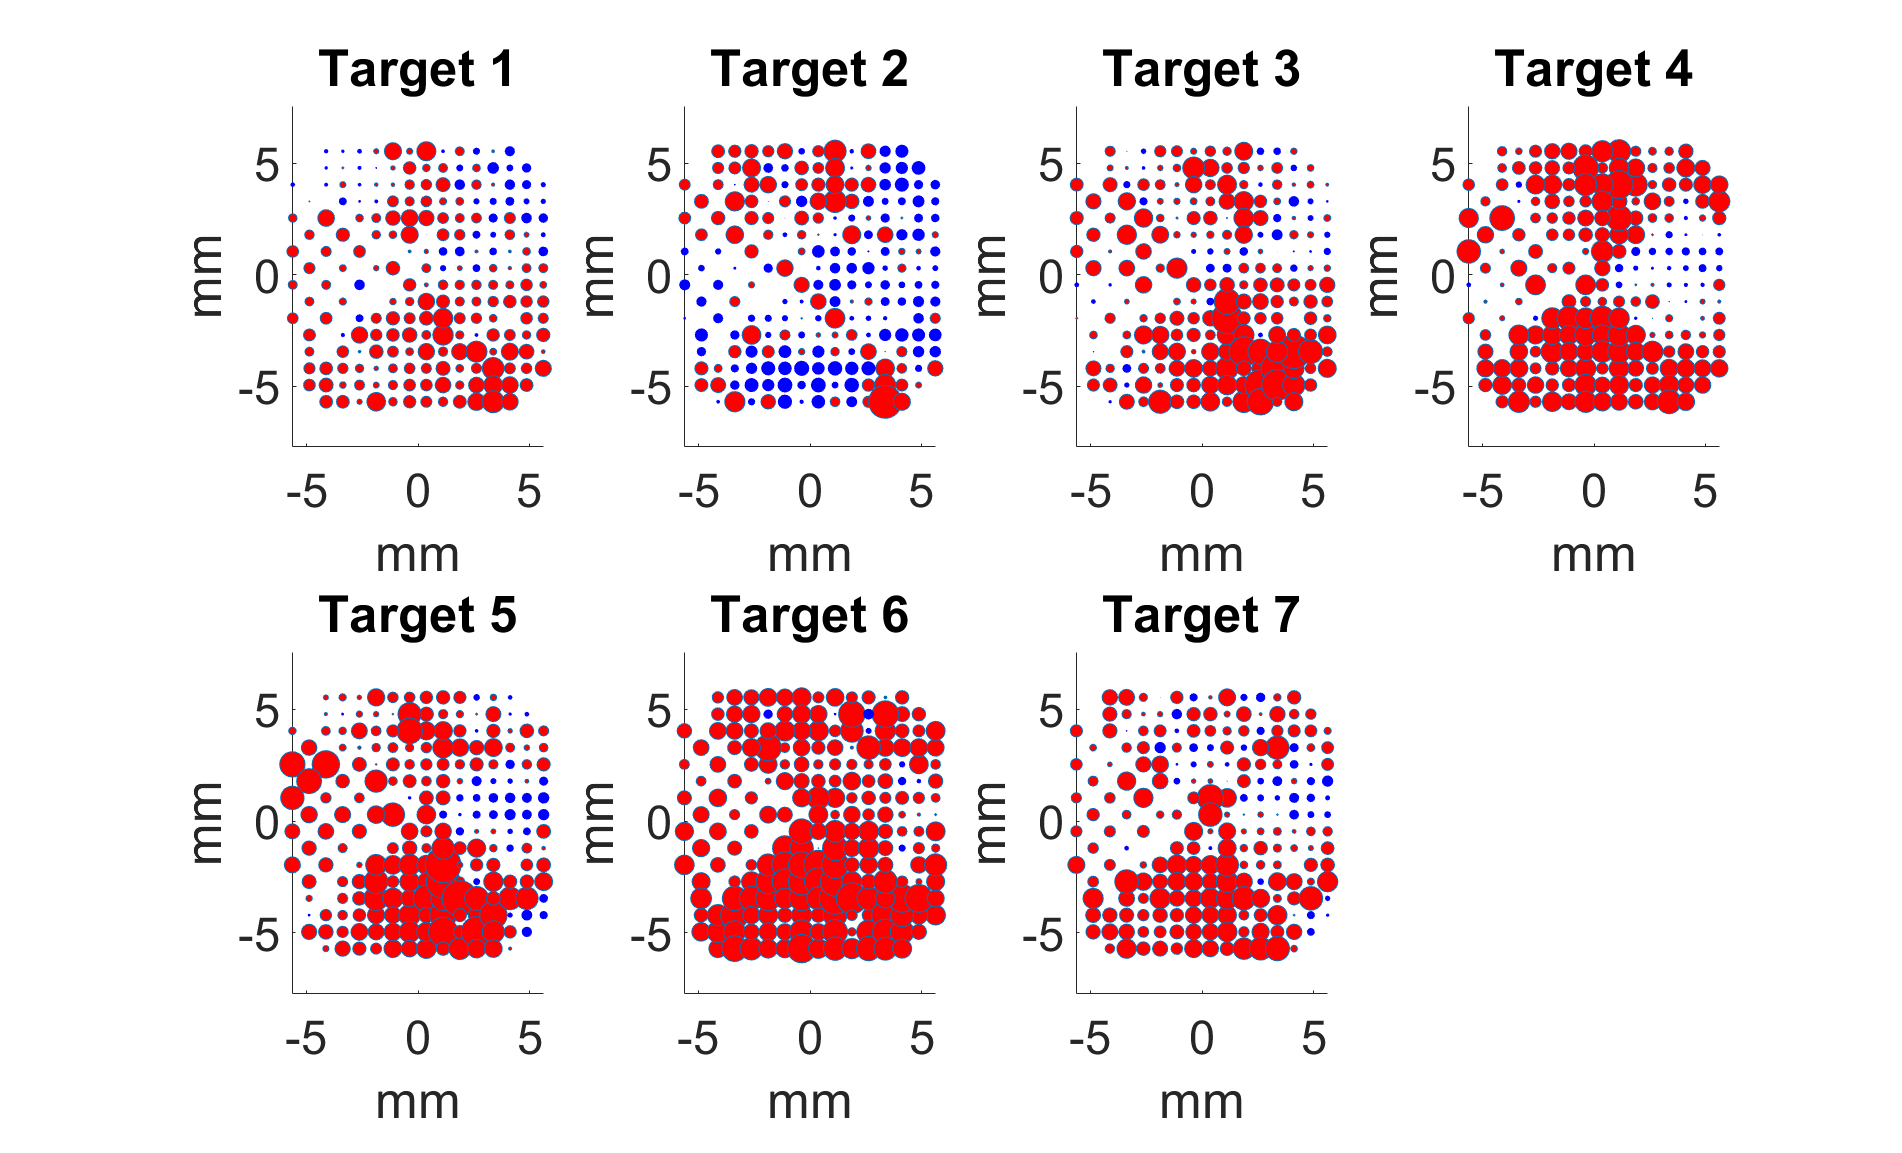

%load 20180329.003.experiment
%load 180329/mat/trials
drive_idx = 1;
freqRange = [0 12];


%freqRange_display_pool = [70 85];
labelElectrode = 0;
onlyLowered = 0;%0 for ECOG

acList = [experiment.hardware.microdrive(drive_idx).electrodes.acquisitionid];
magFac = 100;
textShift = 0.1;

%load the correct P_chamber index
if drive_idx == 1
    P_chamber = drmap_coordTransform_microdrive2chamber(experiment,1)';
elseif drive_idx == 2
     P_chamber = drmap_coordTransform_microdrive2chamber(experiment,2);
else
    disp('Check your index')
end


depthProfile = (Trials(1).Depth{1,drive_idx})'; % in micron
loweredElectrodes  = find(depthProfile > 0);
%then we do some plotting
     
for fri = 1:1
    
    freqRange_display = freqRange(fri,:);
    
    figure('units','normalized','outerposition',[0 0 1 1])
    for targi = 1:7
        

        
        subplot(2,4,targi)
        bubbleValues = squeeze(mean(trLfpData_spec_feature(trial_TargetAssigned == targi,1:211,fri),1));
        % process the bubble values, red as increase and blue means decrease
        %increasing
        
        if onlyLowered
            bubbleValues_inc_indices = intersect(find(bubbleValues >0), loweredElectrodes);
            bubbleValues_dec_indices = intersect(find(bubbleValues  < 0), loweredElectrodes);
        else
            bubbleValues_inc_indices = find(bubbleValues >0 );
            bubbleValues_dec_indices = find(bubbleValues < 0);
        end
        
        bubbleValues_zero_indices = find(bubbleValues == 0);
        
        scatter(P_chamber(bubbleValues_inc_indices,1),P_chamber(bubbleValues_inc_indices,2)...
            ,bubbleValues(bubbleValues_inc_indices) * magFac, ...
            'MarkerFaceColor','r')
        axis equal
        
        %label the negative z-scores
        hold on
        
        scatter(P_chamber(bubbleValues_dec_indices,1),P_chamber(bubbleValues_dec_indices,2)...
            ,abs(bubbleValues(bubbleValues_dec_indices)) * magFac,...
            'MarkerFaceColor','b','MarkerEdgeColor','none')
        

        scatter(P_chamber(bubbleValues_zero_indices,1),P_chamber(bubbleValues_zero_indices,2)...
            ,magFac  / 2, 'MarkerFaceColor','g')
        hold off
%         title(sprintf('ECOG Target %d: Frequency Range %0.1f and %0.1f', ...
%             targi,freqRange_display(1),freqRange_display(2)))
        title(sprintf('Target %d',targi))
        xlabel('mm')
        ylabel('mm')
        
        set(gca,'fontSize',28)
        %label the electrodes
        if labelElectrode
            
            hold on
            if drive_idx == 1 %ECOG 
                for i = 1:size(s_z_targ_features,2)
                    text(P_chamber(i,1)+textShift,...
                        P_chamber(i,2)....
                        ,num2str(i))
                end
            elseif drive_idx == 2 %SC32
                for i = 1:length(loweredElectrodes)
                    text(P_chamber(loweredElectrodes(i),1)+textShift,...
                        P_chamber(loweredElectrodes(i),2)....
                        ,num2str(i))
                end
            else
                disp('Check drive index number')
            end
            hold off
        end
    end
end
print(gcf, 'centerout_ECOG_dist.jpg', '-djpeg', '-r600');